Multivariate gaussian

% let's generate u and v
% mu(u)=-1 sigma(u)=sqrt(2)
% mu(v)= 2 sigma(v)=sqrt(4)
% with COV[u,v]=-0.7

muu=-1; 
sigmau=sqrt(2);

muv= 2;
sigmav=sqrt(4);

covuv=-0.7;

S=[sigmau^2 covuv; covuv sigmav^2] 

S =    2.000000000000000  -0.700000000000000
  -0.700000000000000   4.000000000000000




mu=[muu,muv]' 

mu =     -1
     2


rng(1)

ntr=1e6;

ures=zeros(ntr,1);
vres=zeros(ntr,1);

 [V,D]=eig(inv(S))

V =    0.300639384879094  -0.953737888656795
  -0.953737888656795  -0.300639384879094


D =    0.236930018432308                   0
                   0   0.562004735229477




for i=1:ntr
  xx=ournormal'; % we need a vector
  w=mu+V*inv(sqrt(D))*xx;
  ures(i)=w(1);
  vres(i)=w(2);
end

checkmuu=sum(ures)/ntr

checkmuu =   -0.999897031312443


checkmuv=sum(vres)/ntr

checkmuv =    1.999014252566821



checkmuu2=sum(ures.*ures)/ntr;
checkmuv2=sum(vres.*vres)/ntr;

checkvaru=checkmuu2-checkmuu^2

checkvaru =    1.999293524295138


checkvarv=checkmuv2-checkmuv^2

checkvarv =    4.005121020504345



sum((ures-checkmuu).*(vres-checkmuv))/ntr

ans =   -0.701485801631791


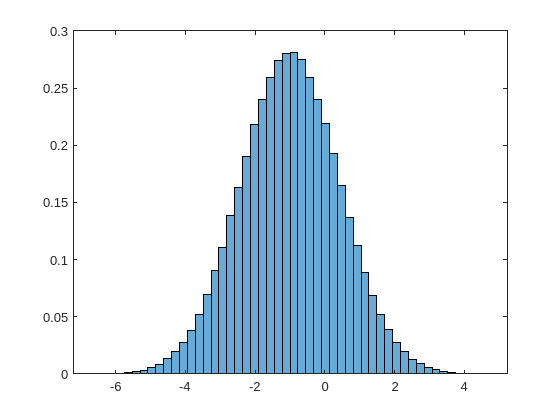



nbins=50;
histogram(ures,nbins,'BinLimits',[muu-4*sigmau,muu+4*sigmau],'Normalization','pdf')

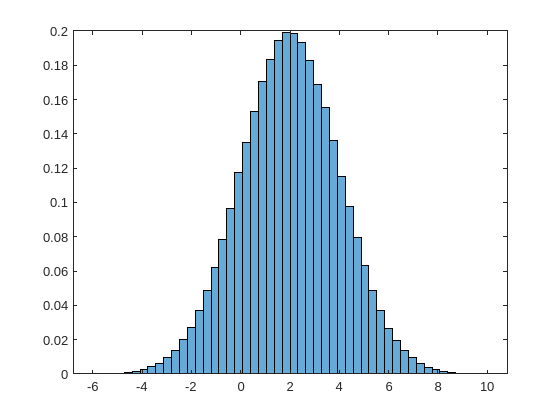

histogram(vres,nbins,'BinLimits',[muv-4*sigmav,muv+4*sigmav],'Normalization','pdf')

Exchange/spread option

format long
% u and v with volatility 0.4 and 0.3 with correlation 0.7, payoff v-u

r=0.05;
sigmau=0.4;
sigmav=0.3;

T=5/12;

u0=60;
v0=50;

% correlation = cov/sigmau/sigmav

S=[sigmau^2 0.7*sigmav*sigmau; 0.7*sigmav*sigmau sigmav^2] 

S =    0.160000000000000   0.084000000000000
   0.084000000000000   0.090000000000000




mu=[r,r]' 

mu =    0.050000000000000
   0.050000000000000


[V,D]=eig(inv(S))

V =   -0.832050294337844  -0.554700196225229
  -0.554700196225229   0.832050294337844


D =    4.629629629629629                   0
                   0  29.411764705882348




rng(5)
npt=1e6;
ff1=0;
ff2=0;
for i=1:npt
     xx=ournormal';
     w=V*inv(sqrt(D))*xx;

    utm=u0*exp((r-sigmau^2/2)*T+sqrt(T)*w(1));
    vtm=v0*exp((r-sigmav^2/2)*T+sqrt(T)*w(2));
    tmp=exp(-r*T)*max([(vtm-utm) 0]);
    ff1=ff1+tmp;
    ff2=ff2+tmp^2;
end
ff1/npt

ans =    0.864877921227604


sqrt(ff2/npt-(ff1/npt)^2)/sqrt(npt)

ans =    0.002495346268551


Barrier option

clear
format long
rng(1);
% dx =axdt+bxsqrt(dt)*xi
r=0.06;
sigma=0.2;
nsteps=365; % 
tf=1;       % 1 year, checked daily


n=10000;

t0=0;
s0=100;
barrier=99;
k=100;

dt=(tf-t0)/nsteps; 


ff1=0;
ff2=0;
for j=1:n % need a column vector to use thw same sintax as before
    stm=s0;
    passed=1;
    for i=1:nsteps
        xi=ournormal;
        stm=stm*exp((r-sigma^2/2)*dt + sigma*sqrt(dt)*xi(1));
        if(stm <= barrier)
            passed=0;
            break;
        end
    end
    tmp=exp(-r*tf)*max([(stm-k) 0])*passed;
    
    ff1=ff1+tmp;
    ff2=ff2+tmp^2;

end

res=ff1/n

res =    2.333062712915690


err=sqrt(ff2/n-res^2)/sqrt(n)

err =    0.094293082786582


Asian option

S0=50;
k=50;
r=0.1;
sigma=0.4;
T=5/12;
M=5;
npt=1e5;
[res,err]  =ref_ACall(1,S0,k,r,sigma,T,M,npt)

res =    3.997814930207904


err =    0.018918531410908


[resa,erra]=ref_ACall(2,S0,k,r,sigma,T,M,npt)

resa =    3.987453250587992


erra =    0.013938696877252


S0=50;
k=55;
r=0.05;
sigma=0.4;
T=12/12;
M=12;
npt=1e6;
[res,err]=ref_ACall(1,S0,k,r,sigma,T,M,npt)

res =    3.445463028294033


err =    0.007261145112990


[resa,erra]=ref_ACall(2,S0,k,r,sigma,T,M,npt)

resa =    3.458307171564618


erra =    0.006412335795402


Check some correlation to build a control-variate strategy


k=55;
r=0.05;
sigma=0.4;
T=12/12;
M=12;
npt=1e4;
xvec=zeros(npt,1);
yvec=zeros(npt,1);
zvec=zeros(npt,1);


dt=T/M;
a=(r-sigma^2/2)*dt;
b=sigma*sqrt(dt);

for i=1:npt
    % using a random s0 
    S0=(70-30)*rand(1)+30;
    stm=zeros(M,1);
    xi=ournormal;
    stm(1)=S0*exp(a+b*xi(1));
    for j=2:M
        xi=ournormal;
        stm(j)=stm(j-1)*exp(a+b*xi(1));
    end
    xvec(i)=exp(-r*T)*max([(sum(stm)/M-k) 0]);
    yvec(i)=exp(-r*T)*(sum(stm)+S0)/M; % +
    zvec(i)=exp(-r*T)*max([(prod(stm)^(1/M)-k) 0]);
end

clf
hold on

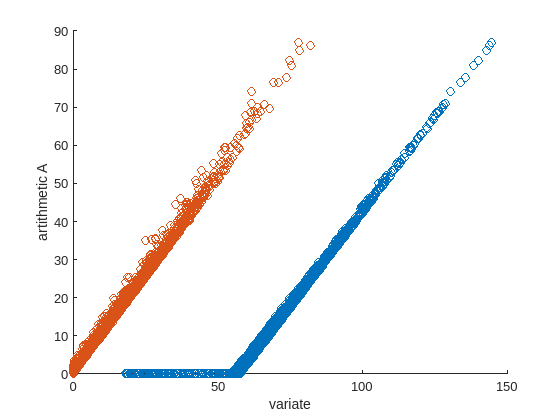

res = 3.4480

err = 0.0073

resv = 3.4507

errv = 0.0038

res = 3.4555

err = 0.0073

resv = 3.4488

errv = 4.6486e-04

res = 3.4461

err = 0.0073

ress = 3.4488

errs = 0.0042

scatter(yvec,xvec)
scatter(zvec,xvec)
ylabel("artithmetic A")
xlabel("variate")
hold off